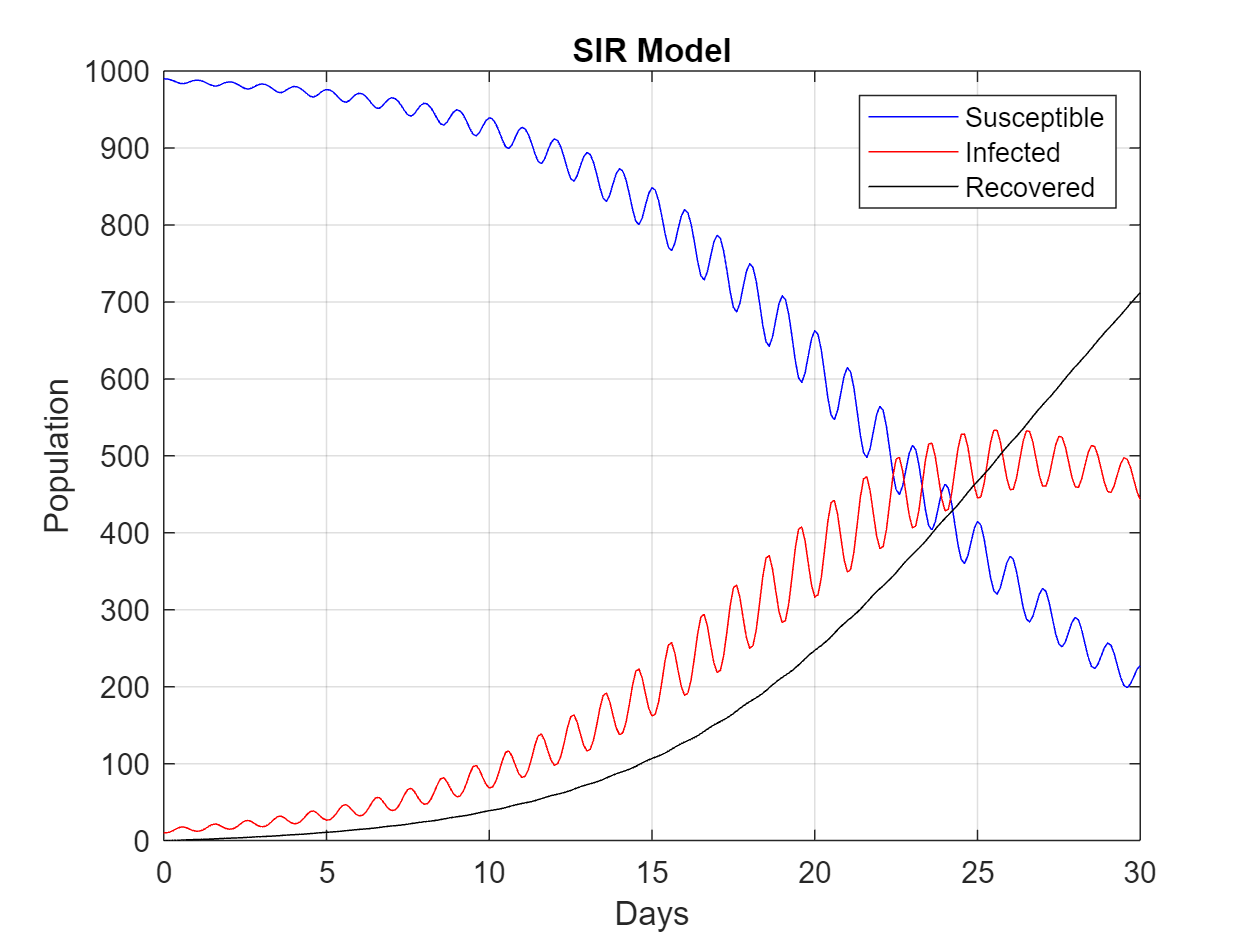

clear
clc

% Initial conditions

h = 0.1; % time step
S0 = 990; 
I0 = 10;
R0 = 0; 
B0 = 0.3;
a = 0; % day 0 
b = 30; % day 30 (time simulation)
n = (b-a)/h; % step size
B = zeros(1,n+1); % variable transmission rate
A = 5; % amplitude
w = (2*pi*365)/365; % frequency
g = 0.1; % gamma value recovery rate
t = linspace(a,b,n+1);
S = zeros(1,n+1);
I = zeros(1,n+1);
R = zeros(1,n+1);
S(1) = S0;
I(1) = I0;
R(1) = R0;
B(1) = B0;
N = S0 + R0 + I0; % total population (constant)
f = (1/b)*(0:(N/2)); % frequency for fft
f = f(1,(1:301));


% Transmission equations and B(t)

fS = @(B,S,I) -B*S*I / N; % Susceptible function
fI = @(B,S,I) (B*S*I / N) - g*I; % Infected function
fR = @(I) g*I; % Recovered function
fB = @(t) B0*(1+(A*sin(w*t))); % transmission variation

% loop to get B(t) values to plug into functions

j = 0;
for u = 1:n % maybe populate B then plug into runge
    j = t(u);
    B(u) = fB(j);
end


for i = 1:n
    
    K1S = fS(B(i),S(i),I(i));
    K2S = fS(B(i),S(i)+0.5*h, I(i)+0.5*K1S*h);
    K3S = fS(B(i),S(i)+0.5*h,I(i)+0.5*K2S*h);
    K4S = fS(B(i),S(i+1),I(i)+K3S*h);
    S(i+1) = S(i) + (K1S+2*K2S+2*K3S+K4S)*(h/6);

    K1I = fI(B(i),S(i),I(i));
    K2I = fI(B(i),S(i) + 0.5*h, I(i) + 0.5*K1I*h);
    K3I = fI(B(i),S(i) + 0.5*h, I(i) + 0.5*K2I*h);
    K4I = fI(B(i),S(i+1), I(i) + K3I*h);
    I(i+1) = I(i) + (K1I+2*K2I+2*K3I+K4I)* (h/6);

    K1R = fR(I(i));
    K2R = fR(I(i) + 0.5*K1R*h);
    K3R = fR(I(i) + 0.5*K2R*h);
    K4R = fR(I(i) + K3R*h);
    R(i+1) = R(i) + (K1R+2*K2R+2*K3R+K4R)*(h/6);
end

plot(t,S,'b-')
grid on
hold on 
plot(t,I,'r-')
plot(t,R,'k-')
legend('Susceptible','Infected','Recovered','Location','northeast')
title 'SIR Model'
xlabel('Days')
ylabel('Population')
hold off

Discussion of SIR plot with added variable transmission rate.

Both the susceptible population, as well as the Infected population, rise and fall opposite one another, to represent the periods of low transmission due to nocturnal behavior, and the higher transmission periods to represent the active daily transmission.

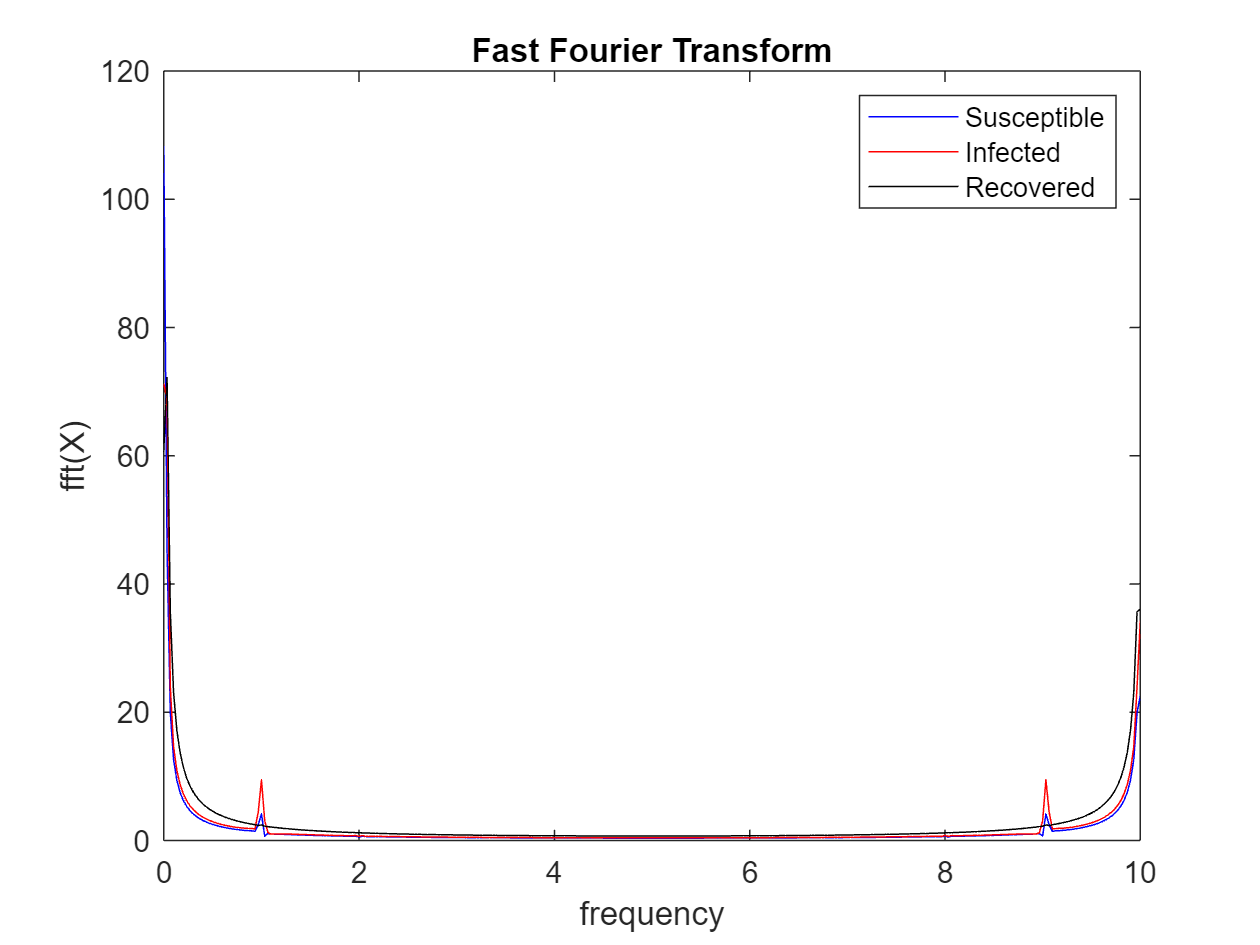


SpectrumS = fft(S); % susceptible conversion
SpectrumR = fft(R); % recovered conersion
SpectrumI = fft(I); % infected conversion
SpectrumS = abs(SpectrumS/N/2); 
Spectrums = SpectrumS(1:301);
SpectrumR = abs(SpectrumR/N);
Spectrumr = SpectrumR(1:301);
SpectrumI = abs(SpectrumI/N);
Spectrumi = SpectrumI(1:301);
Spectrums(2:end-1) = 2*Spectrums(2:end-1);
Spectrumi(2:end-1) = 2*Spectrumi(2:end-1);
Spectrumr(2:end-1) = 2*Spectrumr(2:end-1);


figure(1)
plot(f,Spectrums,'b-')
hold on
plot(f,Spectrumi,'r-')
plot(f,Spectrumr,'k-')
xlabel('frequency')
ylabel('fft(X)')
legend('Susceptible','Infected','Recovered','Location','northeast')
title('Fast Fourier Transform')
hold off

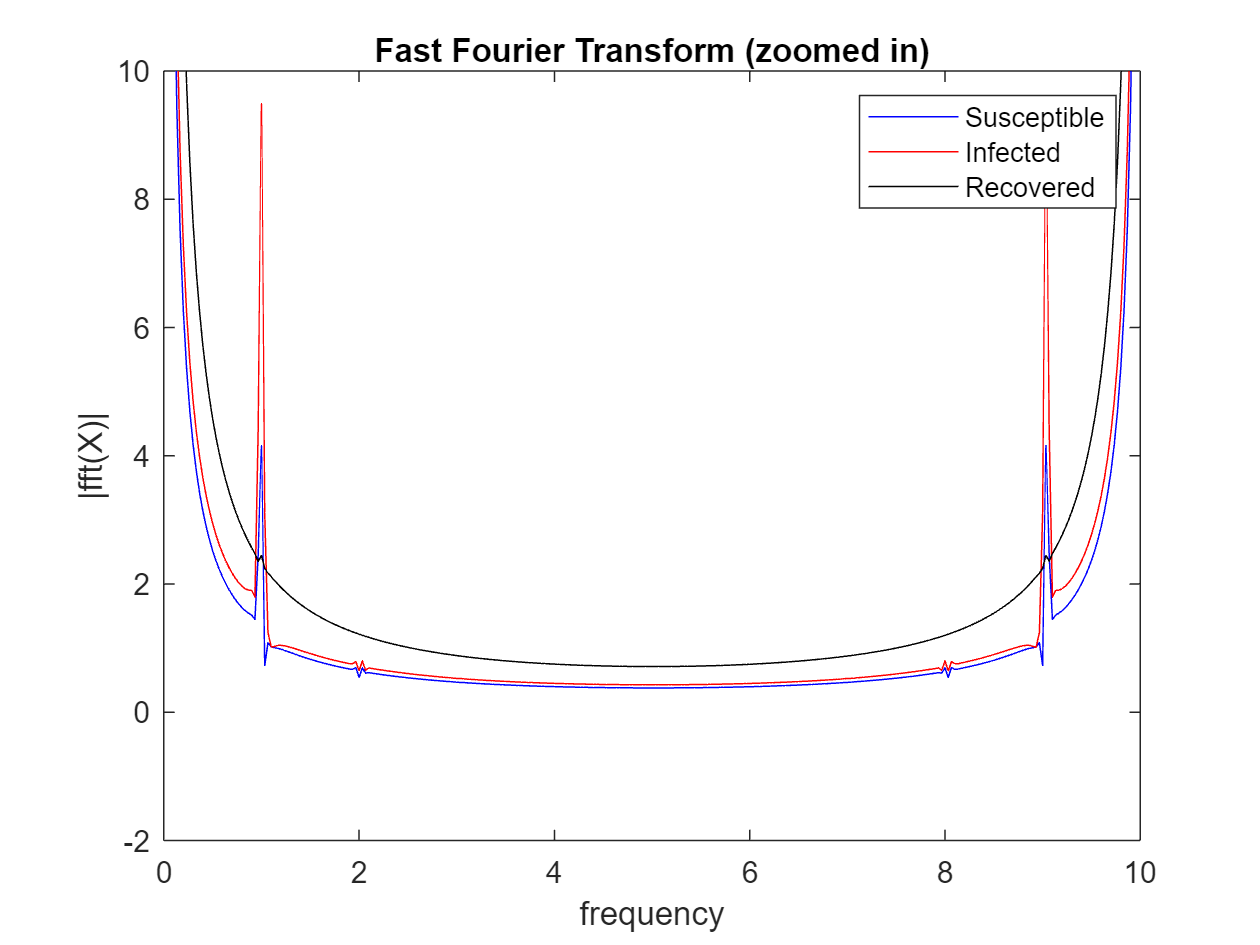


figure(2)
plot(f,Spectrums,'b-')
hold on
plot(f,Spectrumi,'r-')
plot(f,Spectrumr,'k-')
xlabel('frequency')
ylabel('|fft(X)|')
ylim([-2 10])
legend('Susceptible','Infected','Recovered','Location','northeast')
title('Fast Fourier Transform (zoomed in)')
hold off

The peaks in frequency of the Fast Fourier Transform suggest that the highest transmission rates occur during the peak crossover times of day to night, and night to day cycles. Physically this would hold, as the greatest crossover of individuals will happen in between the night and day time. Therefor, the greatest transmission should happen during the greatest cross over of individuals.